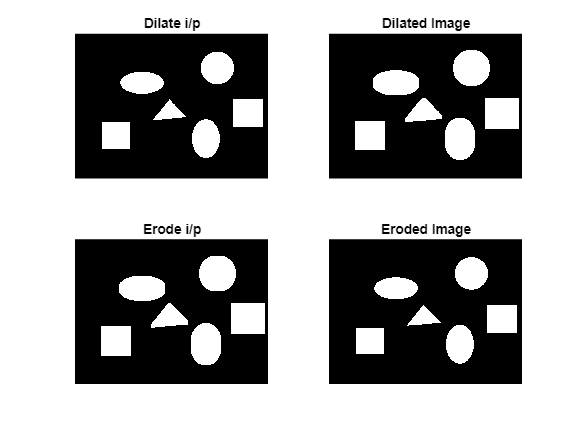

clc;
close all;
clear all;
org_img = imread('mor.png');
bw_d = im2bw(rgb2gray(org_img));
se = strel('square', 18);
dilate_img = imdilate(bw_d, se);

erode_img = imerode(dilate_img, se);

subplot(2,2,1)
imshow(bw_d)
title('Dilate i/p')

subplot(2,2,2)
imshow(dilate_img)
title('Dilated Image')

subplot(2,2,3)
imshow(dilate_img)
title('Erode i/p')

subplot(2,2,4)
imshow(erode_img)
title('Eroded Image')